# ODE Lab: Creating your own ODE solver in MATLAB

In this lab, you will write your own ODE solver for the Improved Euler method (also known as the Heun method), and compare its results to those of `ode45`.

You will also learn how to write a function in a separate m-file and execute it.

Opening the m-file lab3.m in the MATLAB editor, step through each part using cell mode to see the results. Compare the output with the PDF, which was generated from this m-file.

There are six (6) exercises in this lab that are to be handed in on the due date. Write your solutions in the template, including appropriate descriptions in each step. Save the .m files and submit them online on Quercus.

## Student Information

Student Name: Regis Zhao

Student Number: 1007070660

## Creating new functions using m-files.

Create a new function in a separate m-file:

Specifics: Create a text file with the file name f.m with the following lines of code (text):

Now MATLAB can call the new function f (which simply accepts 3 numbers and adds them together). To see how this works, type the following in the matlab command window: sum = f(1,2,3)

## Exercise 1

Objective: Write your own ODE solver (using the Heun/Improved Euler Method).

Details: This m-file should be a function which accepts as variables (t0,tN,y0,h), where t0 and tN are the start and end points of the interval on which to solve the ODE, y0 is the initial condition of the ODE, and h is the stepsize. You may also want to pass the function into the ODE the way `ode45` does (check lab 2).

Note: you will need to use a loop to do this exercise. You will also need to recall the Heun/Improved Euler algorithm learned in lectures. 

% IMPROVED EULER'S METHOD

% function [t, y] = f(func,t0,tN,y0,h)
%     t = t0:h:tN;
%     y = NaN(1, length(t));
%     y(1) = y0;
%     for i = 2:length(t)
%         m_prev = func(t(i-1), y(i-1));
%         sol_cur = y(i-1) + m_prev*h;
%         m_cur = func(t(i), sol_cur);
%         S = (m_prev + m_cur) / 2;
%         y(i) = y(i-1) + S*h;
%     end
% end

## Exercise 2

Objective: Compare Heun with `ode45`.

Specifics: For the following initial-value problems (from lab 2, exercises 1, 4-6), approximate the solutions with your function from exercise 1 (Improved Euler Method). Plot the graphs of your Improved Euler Approximation with the `ode45` approximation.

(a) `y' = y tan t + sin t, y(0) = -1/2` from `t = 0` to `t = pi`

(b) `y' = 1 / y^2 , y(1) = 1` from `t=1` to `t=10`

(c) `y' = 1 - t y / 2, y(0) = -1` from `t=0` to `t=10`

(d) `y' = y^3 - t^2, y(0) = 1` from `t=0` to `t=1`

f_a = @(t,y) y*tan(t) + sin(t);
f_b = @(t,y) 1 / y^2;
f_c = @(t,y) 1 - t*(y/2);
f_d = @(t,y) y^3 - t^2;

[t_a, y_a] = f(f_a, 0, pi, -1/2, 0.01);
soln_a = ode45(f_a, [0, pi], -1/2);

[t_b, y_b] = f(f_b, 1, 10, 1, 0.01);
soln_b = ode45(f_b, [1, 10], 1);

[t_c, y_c] = f(f_c, 0, 10, -1, 0.01);
soln_c = ode45(f_c, [0, 10], -1);

[t_d, y_d] = f(f_d, 0, 1, 1, 0.01);
soln_d = ode45(f_d, [0, 1], 1);

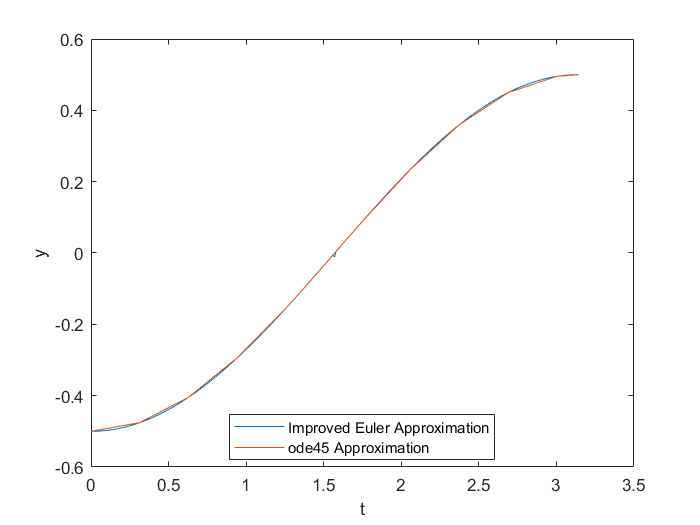


plot(t_a, y_a, soln_a.x, soln_a.y);
xlabel('t');
ylabel('y');
legend('Improved Euler Approximation', 'ode45 Approximation', 'Location', 'Best');

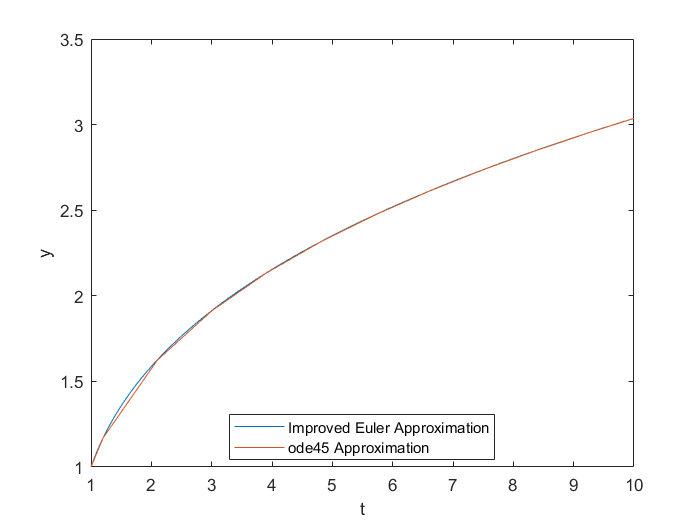

plot(t_b, y_b, soln_b.x, soln_b.y);
xlabel('t');
ylabel('y');
legend('Improved Euler Approximation', 'ode45 Approximation', 'Location', 'Best');

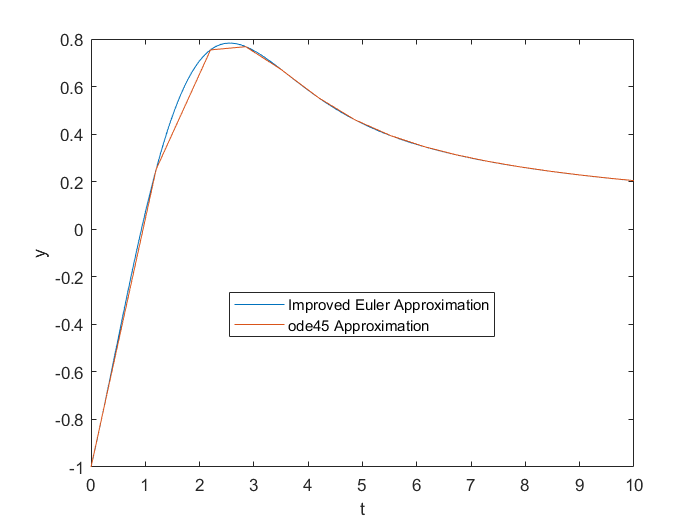

plot(t_c, y_c, soln_c.x, soln_c.y);
xlabel('t');
ylabel('y');
legend('Improved Euler Approximation', 'ode45 Approximation', 'Location', 'Best');

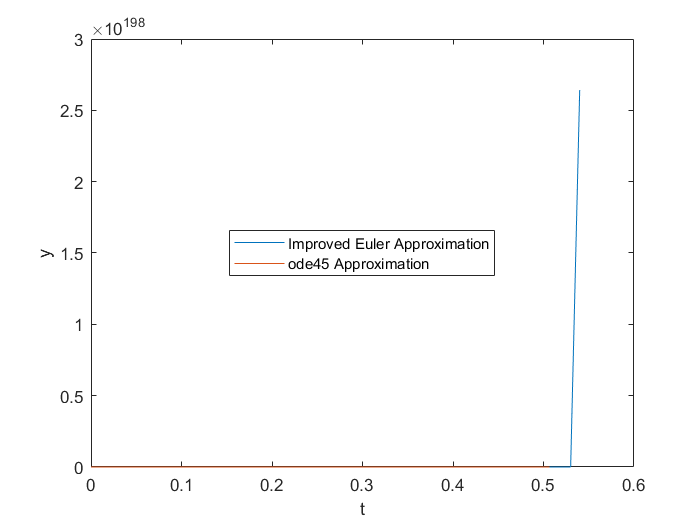

plot(t_d, y_d, soln_d.x, soln_d.y);
xlabel('t');
ylabel('y');
legend('Improved Euler Approximation', 'ode45 Approximation', 'Location', 'Best');

Comment on any major differences, or the lack thereof. You do not need to reproduce all the code here. Simply make note of any differences for each of the four IVPs.

% For (a), (b), and (c), there are no major differences between the
% Improved Euler method and ode45. For (d), the ode45 approximation ends at
% around t = 0.5 while the Improved Euler Approximation suddenly spikes up
% a bit after t = 0.5.

## Exercise 3

Objective: Use Euler's method and verify an estimate for the global error.

Details: 

(a) Use Euler's method (you can use euler.m from iode) to solve the IVP

`y' = 2 t sqrt( 1 - y^2 ) , y(0) = 0`

from `t=0` to `t=0.5`.

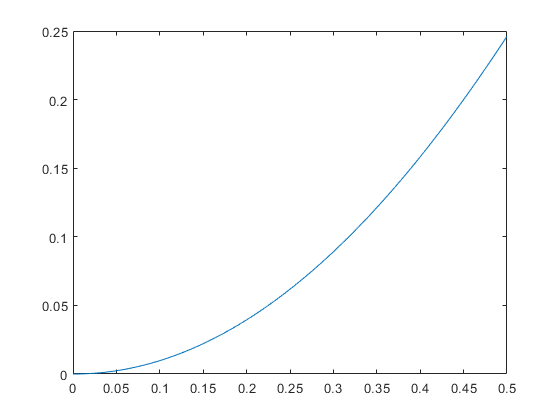

f = @(t,y) 2.*t.*sqrt(1-y.^2);
t0 = 0;
y0 = 0;
t = linspace(t0, 0.5, 200);
soln = euler(f,y0,t);
plot(t, soln);

(b) Calculate the solution of the IVP and evaluate it at `t=0.5`.

% Solution of IVP: y = sin(t^2)
% y(0.5) ~= 0.2474

(c) Read the attached derivation of an estimate of the global error for Euler's method. Type out the resulting bound for En here in a comment. Define each variable.

% En <= (1+M)(deltat)(e^(M(deltat(n)))-1) / 2

% M is some value greater than 0 such that M >= |f|, M >= |df/dt|, and M >=
% |df/dy|. 
% deltat is the size of the steps.
% n is the number of steps taken for the approximation.

% To find M, we find the maximum value that |f|, |df/dt|, and |df/dy| can
% take on the interval [t0, tN] (i.e. [0, 0.5]), and assign M to the
% maximum of those three values. Maximum value for |f| is 1; for |df/dt| is
% 2; for |df/dy| is around 0.2553. So M = 2.

% Plugging M = 2, deltat = 0.0025, and n = 200 into the formula for En, we
% obtain a bound for En:
% En <= 0.00644

(d) Compute the error estimate for `t=0.5` and compare with the actual error.

% Error Estimate = 0.00644
% Actual Error = |y_n - y(t_n)| = |0.2462 - 0.2474| = 0.0012
% The actual error is less than the error estimate.

(e) Change the time step and compare the new error estimate with the actual error. Comment on how it confirms the order of Euler's method.

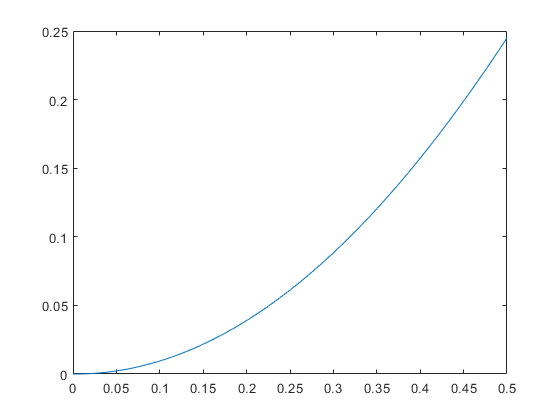

t = linspace(t0, 0.5, 100);
soln = euler(f,y0,t);
plot(t, soln);


% Plugging in M = 2, deltat = 0.005, n = 100, we obtain a new error
% estimate:
% En <= 0.01289
% Actual Error = |y_n - y(t_n)| = |0.2450 - 0.2474| = 0.0024

% The actual error is less than the error estimate.

% After increasing the step size by a factor of 2, both the error estimate
% and the actual error also increased by a factor of 2. The global error
% is linearly proportional to step size, confirming that Euler's method is
% of first order.

## Adaptive Step Size

As mentioned in lab 2, the step size in `ode45` is adapted to a specific error tolerance.

The idea of adaptive step size is to change the step size `h` to a smaller number whenever the derivative of the solution changes quickly. This is done by evaluating f(t,y) and checking how it changes from one iteration to the next.

## Exercise 4

Objective: Create an Adaptive Euler method, with an adaptive step size `h`.

Details: Create an m-file which accepts the variables `(t0,tN,y0,h)`, as in exercise 1, where `h` is an initial step size. You may also want to pass the function into the ODE the way `ode45` does.

Create an implementation of Euler's method by modifying your solution to exercise 1. Change it to include the following:

(a) On each timestep, make two estimates of the value of the solution at the end of the timestep: `Y` from one Euler step of size `h` and `Z` from two successive Euler steps of size `h/2`. The difference in these two values is an estimate for the error.

(b) Let `tol=1e-8` and `D=Z-Y`. If `abs(D)<tol`, declare the step to be successful and set the new solution value to be `Z+D`. This value has local error `O(h^3)`. If `abs(D)>=tol`, reject this step and repeat it with a new step size, from (c).

(c) Update the step size as `h = 0.9*h*min(max(tol/abs(D),0.3),2)`.

Comment on what the formula for updating the step size is attempting to achieve.

% The formula overall makes the step size smaller in order to
% successfully step through on the next try since smaller step sizes allow
% for more accurate estimates and less error. The minimum and maximum
% functions are applied to make sure there aren't any extreme changes in
% step size.

% ADAPTIVE EULER'S METHOD

% function [t, y] = f_adaptive(func,t0,tN,y0,h)
%     tol = 1e-8;
%     t = [t0];
%     y = [y0];
%     tn = t0;
%     while tn < tN
%         m_prev = func(t(end), y(end));
%         
%         %first case
%         Y = y(end) + m_prev*h;
%         
%         %second case
%         tz = t(end) + h/2;
%         yz = y(end) + m_prev*(h/2);
%         mz = func(tz, yz);
%         Z = yz + mz*(h/2);
%         
%         %error handling
%         D = Z - Y;
%         if abs(D) < tol
%             tn = tn + h;
%             t = [t, tn];
%             y = [y, Z-D];
%         else
%             h = 0.9*h*min(max(tol/abs(D),0.3),2);
%         end
%     end
%     m_prev = func(t(end), y(end));
%     h_last = h - (tn - tN);
%     y_last = y(end) + m_prev*h_last;
%     t = [t, tN];
%     y = [y, y_last];
% end

## Exercise 5

Objective: Compare Euler to your Adaptive Euler method.

Details: Consider the IVP from exercise 3.

(a) Use Euler method to approximate the solution from `t=0` to `t=0.75` with `h=0.025`.

f = @(t,y) 2.*t.*sqrt(1-y.^2);
t0 = 0;
y0 = 0;
tN = 0.75;
h = 0.025;
t = t0 : h : tN;
euler_soln = euler(f,y0,t);

(b) Use your Adaptive Euler method to approximate the solution from `t=0` to `t=0.75` with initial `h=0.025`.

[ae_soln_t, ae_soln_y] = f_adaptive(f, t0, tN, y0, h);

(c) Plot both approximations together with the exact solution.

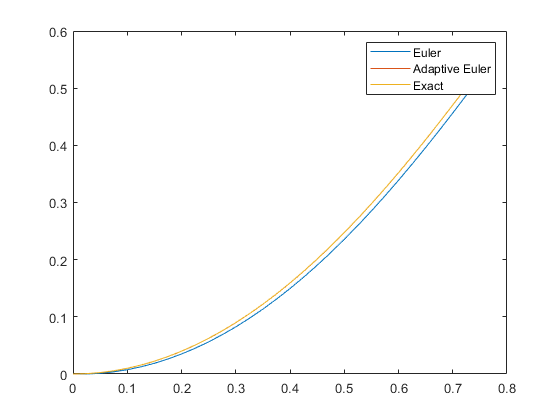

exact_soln = sin(t.^2);
plot(t, euler_soln, ae_soln_t, ae_soln_y, t, exact_soln);
legend('Euler', 'Adaptive Euler', 'Exact')

## Exercise 6

Objective: Problems with Numerical Methods.

Details: Consider the IVP from exercise 3 (and 5).

(a) From the two approximations calculated in exercise 5, which one is closer to the actual solution (done in 3.b)? Explain why.

% The adaptive Euler method is closer to the actual solution because the
% function adapts the step size in order to fit within the error tolerance.
% On the other hand, the Euler method alone does not check against an error
% tolerance - step sizes remain the same no matter how inaccurate the
% solution becomes.

(b) Plot the exact solution (from exercise 3.b), the Euler's approximation (from exercise 3.a) and the adaptive Euler's approximation (from exercise 5) from `t=0` to `t=1.5`.

f = @(t,y) 2.*t.*sqrt(1-y.^2);
t0 = 0;
y0 = 0;
tN = 1.5;
h = 0.025;
t = t0 : h : tN;
euler_soln = euler(f,y0,t);
[ae_soln_t, ae_soln_y] = f_adaptive(f, t0, tN, y0, h);
exact_soln = sin(t.^2);
plot(t, euler_soln, ae_soln_t, ae_soln_y, t, exact_soln);

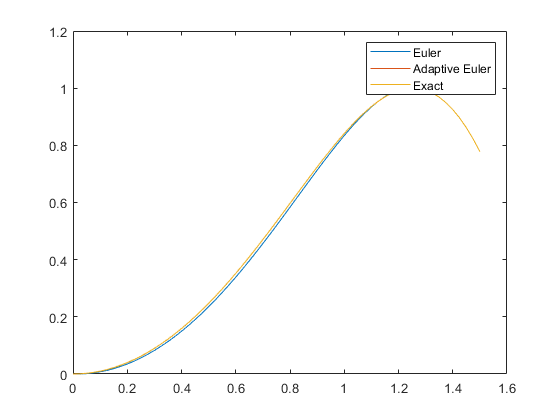

legend('Euler', 'Adaptive Euler', 'Exact')

(c) Notice how the exact solution and the approximations become very different. Why is that? Write your answer as a comment.

% For this ODE, there is a restriction on y, |-1 <= y <= 1|, since any y
% values outside of the range of [-1, 1] will generate a negative value
% under the root. Since they are approximations, it's very likely that the
% function will jump past y = 1 slightly, causing a negative value under
% the root. MATLAB ignores imaginary parts of arguments and therefore the
% function will compute a positive slope, which is why the approximations
% keep increasing, while the exact solution begins to decrease.